%Einteilung Datensätze
cleanedData = readtable("cleanedData.txt")

cleanedData = 23231×16 table
         timestamps         T_Amb_degC    Q_heat    Q_sol    Q_int     EG_LivingKitchen_degC    EG_HallwayEntrance_degC    EG_Utilities_degC    EG_Dressing_degC    EG_Sleeping_degC    EG_Bath_degC    EG_GuestBath_degC    EG_Server_degC    OG_Office_degC    OG_Sleeping_degC    OG_Bath_degC
    ____________________    __________    ______    _____    ______    _____________________    _______________________    _________________    ________________    ________________    ____________    ______________

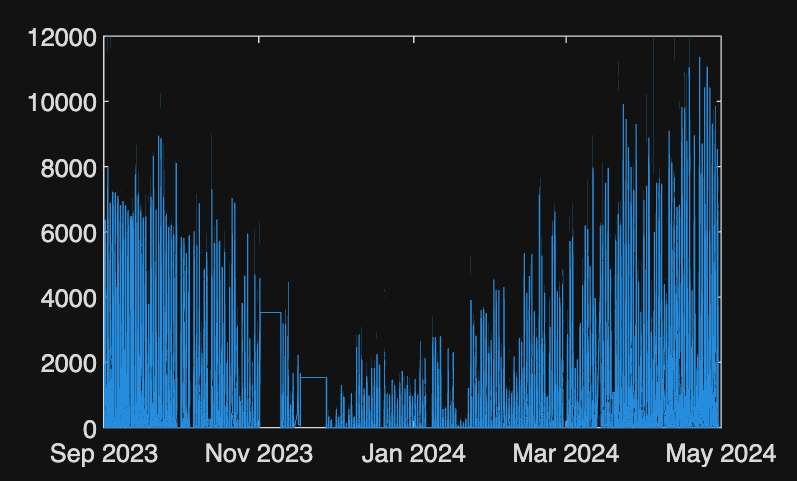



%Ermittlung nicht verwertbarer Zeitabschnitte:
plot(cleanedData.timestamps, cleanedData.Q_sol)

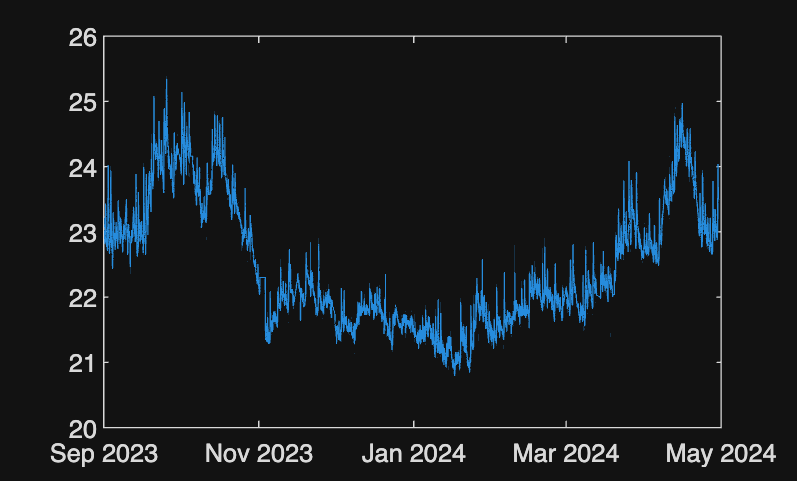

plot(cleanedData.timestamps,cleanedData.EG_Utilities_degC)

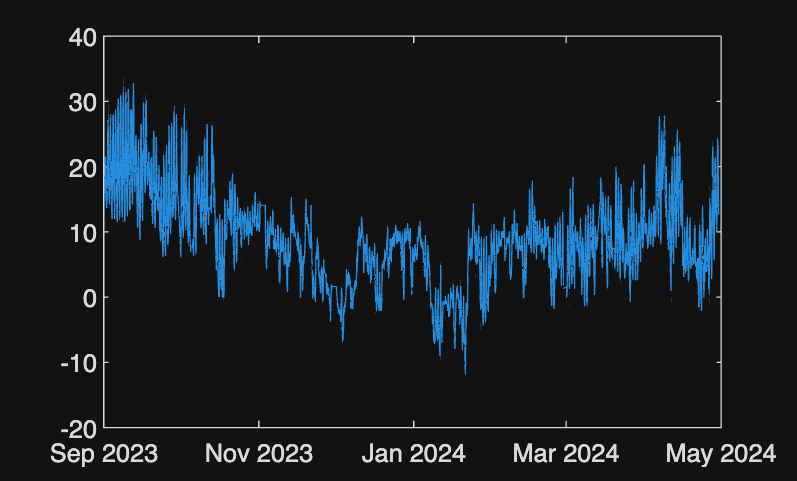

plot(cleanedData.timestamps,cleanedData.T_Amb_degC)

% -> Entfernung von 01.11 10:00-09.11 17:30 & 17.11 10:00 - 27.11 16:00


%Einteilung des Datensatzes periodisch in 2 Wochen Training, 1 Woche
%Validierung, 1 Woche Test
%Dafinition: Woche startet wie Datensatz -> hier 01.09.2023 00.15 und endet
%7 Tage später um 00:00
% Sampling in 15min Takt -> in diesem Beispiel 672 Zeilen pro Woche

%Test Zeile aufrufen

row = cleanedData(cleanedData.timestamps == "01-Sep-2023 00:15:00",:)

row = 1×16 table
         timestamps         T_Amb_degC    Q_heat    Q_sol    Q_int    EG_LivingKitchen_degC    EG_HallwayEntrance_degC    EG_Utilities_degC    EG_Dressing_degC    EG_Sleeping_degC    EG_Bath_degC    EG_GuestBath_degC    EG_Server_degC    OG_Office_degC    OG_Sleeping_degC    OG_Bath_degC
    ____________________    __________    ______    _____    _____    _____________________    _______________________    _________________    ________________    ________________    ____________    _________________  



%[trainInd,valInd,testInd] = divideind(24,[(cleanedData.timestamps == datetime(2023,09,01,00,15):datetime(2023,09,14,00,00))])